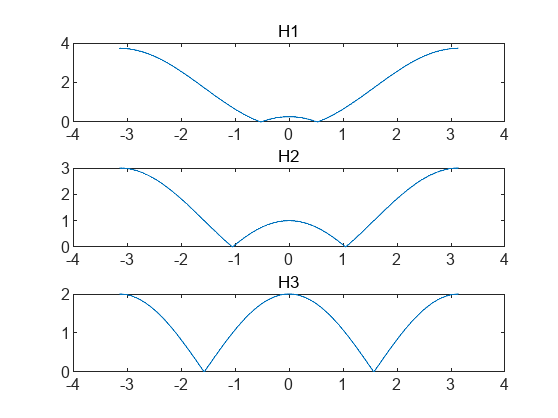

% 7.3
theta = [pi/6 pi/3 pi/2];
w = -pi:0.001:pi;
z = exp(1i*w);
H1 = 1-2*cos(theta(1)).*z.^(-1)+z.^(-2);
H2 = 1-2*cos(theta(2)).*z.^(-1)+z.^(-2);
H3 = 1-2*cos(theta(3)).*z.^(-1)+z.^(-2);
figure
subplot(311)
plot(w, abs(H1));
title('H1');
subplot(312)
plot(w, abs(H2));
title('H2')
subplot(313)
plot(w, abs(H3));
title('H3')

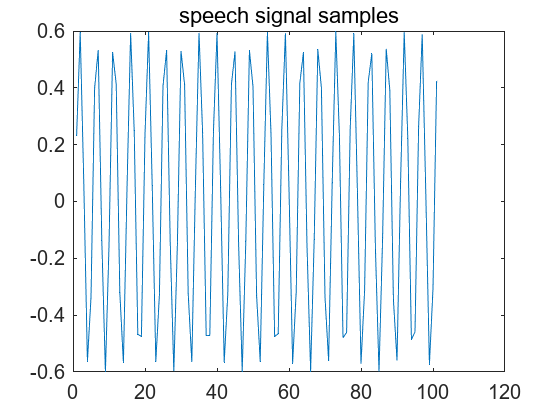

load nspeech1.mat
sound(nspeech1);
figure
plot(nspeech1(100:200));
title('speech signal samples');

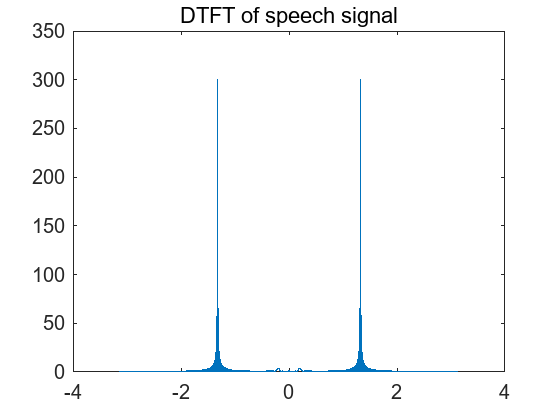

[X ,w]=DTFT(nspeech1(100:1100) ,2^15);
figure
plot(w,abs(X));
title('DTFT of speech signal')

[Xmax,Imax]=max(abs(X));
theta = -w(Imax)

theta = 1.3234

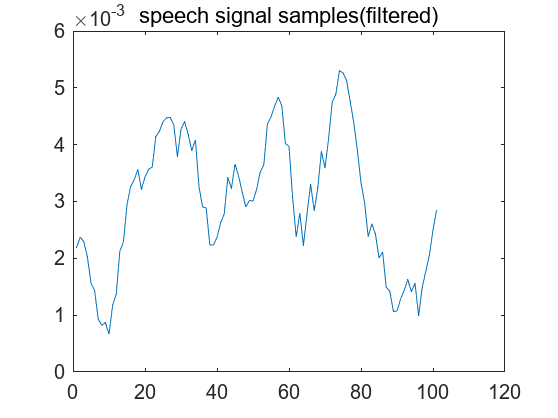


filter_speech = FIRfilter(nspeech1,theta);
sound(filter_speech);
figure
plot(filter_speech(100:200));
title('speech signal samples(filtered)');

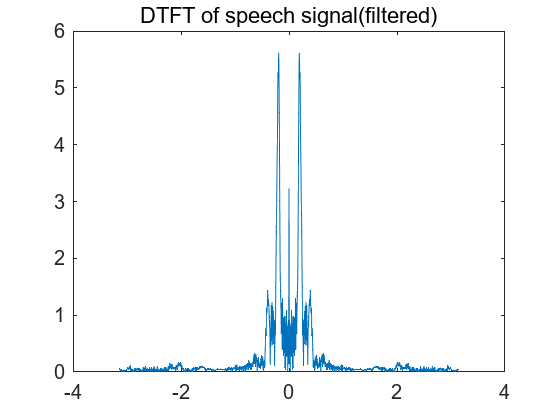

[X_filter ,w]=DTFT(filter_speech(100:1100) ,2^15);
figure
plot(w,abs(X_filter));
title('DTFT of speech signal(filtered)')

function y = FIRfilter(x,theta)
n = 0:3;
h = (n==0)-2*cos(theta)*(n==1)+(n==2);
y = conv(x,h);
end
